# UBC CPSC  302 Num Comp for Alg Problems, 2019W

# Assignment 2

### by [j0k0b] #[42039157]

*Tips: Use the tips from Assignment 1 to get the most credit possible on this and future assignments.  Replace the [Preferred Name or CS-ID] and [Student Number] above. *

## Acknowledgments

You are welcome to work with other students on this assignment, but everything in this file must clearly be your own original work.  Complete the following section to recognize your collaborators on this assignment.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin acknowledgments }~~~~~~~~~~~~~~~~~~~~~}$$


Thanks to [name or CS-ID] for [their contribution].

Thanks to [name or CS-ID] for [their contribution].

Other than the contributions above, this work is my own.

— [j0k0b]


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End acknowledgments }$$


## Question 1

% Set output format for Question 1
digits(100); % 100 digits of precision using variable-precision arithmetic (VPA)

## Question 1.1

The number $\frac{12}{13}\approx$

vpa(12/13) % 12/13 using variable-precision arithmetic (VPA)

$$ans = 0.9230769230769230769230769230769230769230769230769230769230769230769230769230769230769230769230769231$$

... has no exact representation in any decimal floating point system ($\beta=10$) with finite precision $t$.  Is there a finite floating point system (i.e. some finite integer base $\beta$ and precision $t$) in which this number does have an exact representation?  If yes, then describe such a system.  If no, explain why not.

### Answer 1.1

Enter your solution in the space below.

*Tips: You may write your math in *[*LaTeX ($...$)*](https://www.mathworks.com/help/matlab/matlab_prog/insert-equations.html#bvak508)* or insert ****clear, legible**** images of hand-written math.  Your work shown should be logical and have no gaps. Don't just write down the final solution – show your reasoning.*


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$


We know that $x$ can be approximated in the floating point system as $fl(x) = \pm  (\frac{\tilde{d}_0}{\beta^0}+\frac{\tilde{d}_1}{\beta^1}+\dots+\frac{\tilde{d}_{t-1}}{\beta^{t-1}}) \times  \beta^e$, where $\beta =  $ base of the number system; $t = $ precision (# of digits); $L = $ lower bound on exponent *e*; and $U = $upper bound on exponent *e*.  

On the other hand, we can write $\frac{12}{13}$ as $\frac{12}{13} = +(\frac{12}{13^0}) \times  13^{-1}$. We can see that, if we used the floating point system to represent this, then $\beta = 13
$ (base 13 number system), $\tilde{d}_0 = 12$ (rest of the digits = 0), $e = -1$, and $t = 1
$. $\therefore L = -1\ and\ U = 0$.

All in all, we can represent $\frac{12}{13}$ in base 13 number system, where the first digit is 12, and precision is 1 digit (t-1 = 0). 


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 1.2

Answer the same question for the irrational number $e=\exp(1)$.  Note: Here $e$ refers to Euler's number, the [mathematical constant](https://en.wikipedia.org/wiki/E_(mathematical_constant)), not the floating point exponent variable:  

vpa(exp(vpa(1))) % exp(1) using variable-precision arithmetic (VPA)

$$ans = 2.718281828459045235360287471352662497757247093699959574966967627724076630353547594571382178525166427$$

### Answer 1.2

Enter your solution in the space below.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$


Any rational number  ($\frac{p}{q}; s.t.\ q \neq 0 $) can be represented in a floating point system using the base 'q' number system and a large enough finite t precision digits.  

We are given that $e = exp(1)$ is an irrational number. Thus, there is no way to represent this exactly in a floating point system as we cannot write this in the form of $\frac{p}{q}$ with a finite t. 


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 2

The function $f_1(x_0,h)=\sin(x_0+h) - \sin(x_0-h)$ can be transformed into another form, $f_2(x_0,h)$, using the trigonometric formula

                        
$$\sin(\phi) - \sin(\psi) = 2 \cos\left( \frac{\phi+\psi}{2} \right) \sin\left( \frac{\phi-\psi}{2} \right).$$


Thus, $f_1$ and $f_2$ have the same values, in exact arithmetic, for any given argument values $x_0$ and $h$.

## Question 2.1

Derive $f_2(x_0,h)$.

### Answer 2.1

Enter your solution in the space below.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$


We are given $f_1(x_0,h)=\sin(x_0+h) - \sin(x_0-h)$. Using the trigonometric formula given to us, we can express $f_1(x_0,h)$ as $2\cos(\frac{(x_0+h) + (x_0 - h)}{2})\sin(\frac{(x_0+h) - (x_0 - h)}{2})$ $=> 2\cos(\frac{2x_0}{2})\sin(\frac{2h}{2}) => 2\cos(x_0)\sin(h)$. Therefore, we have a new form $f_2(x_0,h) = 2\cos(x_0)\sin(h)$. 


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 2.2

Suggest a formula that avoids cancellation errors for computing the approximation $\frac{f(x_0+h)-f(x_0-h)}{2h}$ to the derivative for $f(x)=\sin(x)$ at $x=x_0$.  Write MATLAB code that implements your formula and computes an approximation of $f'(1.2)$ for $h=10^{-10},10^{-9},\ldots,0.1,1$, plotting the results in a manner comparable to that in Question 1 of Assignment 1.

### Answer 2.2

Enter your solution in the space below.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$


We calculated a different form for the function $\sin(x_0+h) - \sin(x_0-h)$, which was $2\cos(x_0)\sin(h)$, so for $\frac{\sin(x_0+h) - \sin(x_0-h)}{2h}$, we can use the alternative formula $\frac{2\cos(x_0)\sin(h)}{2h}$. The following is the MATLAB script to do the calculation of the approximation of f'(1.2) for $h=10^{-10},10^{-9},\ldots,0.1,1$ :

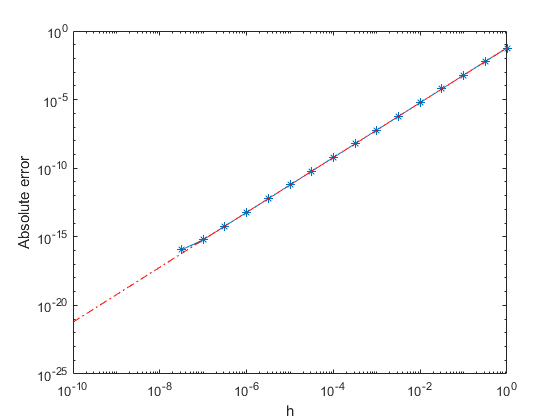

x0 = 1.2;
f0 = sin(x0);
fp = cos(x0); % f prime
ftp = -fp; % f triple prime
i = -10:0.5:0;
h = 10.^i;
err = abs(fp - sin(h).*fp./h);
d_err = abs(ftp)/6*h.^2;
loglog(h, err, '-*');
hold on 
loglog(h, d_err, 'r-.');
xlabel('h')
ylabel('Absolute error')


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 2.3

Explain the difference in accuracy between your results and the results reported in Question 1 of Assignment 1.

### Answer 2.3

Enter your solution in the space below.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$


We deduced in Question 1 of Assignment 1 that discretization error satisfies $f'(x_0) -\frac{f(x_0+h)-f(x_0-h)}{2h} \approx -\frac{h^2}6 f'''(x_0)$ and that this error is $\mathcal{O} (h^2)$. So, $\sin'(x) = \cos(x); x = x_0$ approximation is . We know that both $\frac{f_1}{2h} \ and\ \frac{f_2}{2h}$ are inversely propotional to $h$, and thus, $h^2$ And as the plot from the last question's solution suggest, in the calculated value of $\frac{f_2}{2h}$, where $f_2 = sin(x)$ we see the proof of the aforementioned fact until h is as small as the magnitude of the upper bound of relative error, since the cancellation error is not relatively large (d_err >> roundoff error, until the upper bound of relative error is hit).

On the other hand, in Question 1 of Assignment 1, the cancellation error was relatively large and the values for $\frac{f_1}{h}$ was hugely influenced by the roundoff error when $h < 10^{-5}$.   


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 3

In the statistical treatment of data one often needs to compute the mean and variance, given respectively by

                        
$$\bar{x} = \frac{1}{n} \sum_{i=1}^n x_i, \ \mathrm{Var}(x)=s_1^2=\frac{1}{n}\sum_{i=1}^n \left( x_i - \bar{x} \right)^2,$$


where $x_1, x_2, \ldots, x_n$ are the given data.  Assume that $n$ is large, say $n=10,000$.  It is easy to see that the variance can also be written as

                        
$$\mathrm{Var}(x) = s_2^2 = \frac{1}{n} \left( \sum_{i=1}^n x_i^2 \right) - \bar{x}^2.$$


Now, assuming $\bar{x}$ is given, computing $s_1^2$ requires $n$ subtractions, $n$ multiplications (squares), $n-1$ additions and one division by $n$.  So the total number of operations is $3n$.  On the other hand, computing $s_2^2$ requires $n$ multiplications for squaring $x_i$, $n-1$ additions, one multiplication for squaring $\bar{x}$ and one subtraction.  So the total here is $2n+1$.  Hence $s_2^2$ is cheaper to compute (in the sense of flop count).

## Question 3.1

Which of the two methods to calculate the variance is expected to give more accurate results for $\mathrm{Var}(x)$ in general?  Consider especially the case of narrowly-distributed data, $|\bar{x}| \gg \sqrt{\mathrm{Var}(x)}$.

### Answer 3.1

Enter your solution in the space below.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$


We are given that $n = 10,000$, which is relatively large. So, we have $x_i\ s.t.\ i \in \{1,2,3 \dots10000\} $. We also know that $s^2_2$ is cheaper to compute than $s^2_1$, especially considering such a large dataset. 

But, in the second formula for $\mathrm{Var(x)}$, in the first part of the equation, we see that we are adding the sum of $x^2_i$, and if $x_i$ is very big, $x^2_i$ could lead to overflow and inaccuracy. And, in the second part of the equation, $$we are subtracting $\bar{x}^2$, and if $|\bar{x}| \gg  \sqrt{\mathrm{Var(x)}}$, there could be a huge cancellation error penalty in the formula for $s^2_2$. 

$\therefore$ $s^2_1$ seems, in general, to be more accurate.  


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 3.2

Give a small example, using a decimal system with precision $t=2$ and numbers of your choice, to validate your claims in Answer 3(a).  You may perform calculations by hand or write/run MATLAB code.

### Answer 3.2

Enter your solution in the space below.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$


Let us say that $n = 2,\ x_1 = 2.9\ and\ x_2 = 1.1$. For floating point system representation, let us say $t = 2$.

$\therefore \mathrm{fl(x_1) = 2.9\ ,\ fl(x_2) = 1.1}\ and\ \mathrm{fl(\bar{x}) = 2.0}$. Now, using the fomula from above:

$s^2_1 = \mathrm{fl(\frac{1}{2}( fl((2.9 - 2.0)^2) + fl((1.1-2.0)^2)))} = \mathrm{fl(\frac{1}{2} \times (0.81 + 0.81))} = 0.81$.

$s^2_2 = \mathrm{fl(\frac{1}{2}( fl((8.41 + 1.2)) - fl(2.0^2)} = \mathrm{fl(\frac{1}{2} \times 9.6 - 4.0) = 0.8}$.


$$$$


This validates the claim made in part (a).

Now, we can show this in MATLAB:

digits(2); % t = 2
s1_sq = vpa(1/2*(vpa((2.9-2.0)^2) + vpa((1.1-2.0)^2))) % s_1^2

$$s1\_sq = 0.81$$

s2_sq = vpa(1/2*(vpa((8.41+1.2))) - vpa((2.0)^2)) % s_2^2

$$s2\_sq = 0.8$$

This also certifies that based on the number of digits for precision, the resulting values from $s^2_1\ and\ s^2_2 $ differ.


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Functions

MATLAB requires all functions to be at the [end of the script](https://www.mathworks.com/help/matlab/matlab_prog/local-functions-in-scripts.html).  Enter functions you wrote for this assignment in the space below.

*Tips: You only need to complete this section if you developed and used your own MATLAB function(s) in your code above.  If you do define your own functions, organize your code; use indenting and reasonable variables (e.g. no unused variables or ambiguous names).  Document your code clearly and effectively with comments (*`% This is a comment`*).  Note the specific purpose of each function; indicate input requirements and output results.*


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin functions}~~~~~~~~~~~~~~~~~~~~~}$$



$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End functions}$$
